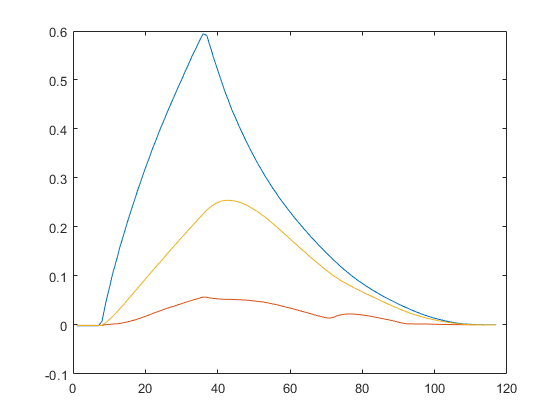

close all;
clear;
clc;
load data/threeTankParameter1.mat;
load hyperparameter.mat;
% hyperparameter1.sigmaF = 1.7;
% hyperparameter1.l= 0.595 ;
% hyperparameter1.sigmaN = 0.05;

%load data/testData1.mat
load dataOut/testData28.mat;
%testData = data;
addpath(genpath('lib'),genpath('gpml-matlab-master'));

xD = [testData.x1,testData.x2,testData.x3];
plot(xD);

dxD = [testData.dx1,testData.dx2,testData.dx3];
%uD = [testData.u1 ,testData.u2];
uD = [testData.u1];

u1Full = uD(15,1);
%u2Half = uD(1,2);
u2 = u1Full * 0;
%u1Half = u1Full * 0.5;
%u1TQ = uD(1)* 0.75

parameter.u1 = u1Full;
parameter.u2 = u2;


%beta1 = [1; 2.4e-05*0.5];
beta1 = [1; 2.39e-05];
beta2 =[3.97E-6;  9.86E-6];
beta3 =[2.468e-05; 2.489e-05];
hyperparameter1.beta = beta1;
hyperparameter2.beta = beta2;
hyperparameter3.beta = beta3;
 noParam.beta = 1

noParam = struct with fields:
    beta: 1



for i = 1: length(xD)
    yD1(i,1) = meanDx1([xD(i,:),uD(i,:)],hyperparameter1);% - dxD(i,1);
    H(:,i) =  meanDx1([xD(i,:),uD(i,:)],noParam).';
end

hyperparameter1 = calcHyperparameter([xD,uD],yD1, @covSEardX1);                                          %!

for i = 1: length(xD)
    yD2(i,1) = meanDx2([xD(i,:),uD(i,:)],hyperparameter2) - dxD(i,2);
end
hyperparameter2 = calcHyperparameter([xD,uD],yD2, @covSEardX2);                                          %!

for i = 1: length(xD)
    yD3(i,1) = meanDx3([xD(i,:),uD(i,:)],hyperparameter3) - dxD(i,3);
end
hyperparameter3 = calcHyperparameter([xD,uD],yD3,@covSEardX3);                                          %!
%save hyperparameter.mat hyperparameter1 hyperparameter2 hyperparameter3

hyperparameterR1 = calcHyperparameter([xD,uD],dxD(:,1),@covSEiso);
hyperparameterR2 = calcHyperparameter([xD,uD],dxD(:,2),@covSEiso);
hyperparameterR3 = calcHyperparameter([xD,uD],dxD(:,3),@covSEiso);

sigmaX = [1e-8, 0, 0; 0, 1e-8, 0; 0, 0, 1e-8];
sigmaY = [5e-6, 0, 0; 0, 5e-6, 0; 0, 0, 5e-6];
%sigmaY = [1e-6, 0, 0; 0, 1e-6, 0; 0, 0, 1e-6];
%sigmaY = sigmaY(1,1);
kernelSE = {@squaredExponentialKernel, @squaredExponentialKernel, @squaredExponentialKernel};
kernelSEARD = {@squaredExponentialKernelARD, @squaredExponentialKernelARD, @squaredExponentialKernelARD};
meanFctTank = {@meanDx1,@meanDx2,@meanDx3};
meanFctZero = {@zeroMean,@zeroMean,@zeroMean};

 hyperparameter1.beta = beta1;
 hyperparameter2.beta = beta2;
 hyperparameter3.beta = beta3;
 hyperparameter1.B = [ 1e-08 , 0 ; 0 , 1000];
 hyperparameter2.B = [ 1e-6 , 0 ; 0 , 1e-6];
 hyperparameter3.B = [ 1e-6 , 0 ; 0 , 1e-6];


%hyperparameter1.sigmaN = hyperparameter1.sigmaN  + 1;
% hyperR = {hyperparameterR1,hyperparameterR2,hyperparameterR3};
hyperBasis = {hyperparameter1, hyperparameter2, hyperparameter3};

parameter.u1 = u1Full *1 ;
parameter.u2 = u1Full * 0;
% parameter.c13 = parameter.c13 * 0.8;
% parameter.c32 = parameter.c32 * 0.6;
% parameter.c2R = parameter.c2R * 0.04;

threeTank = WaterTank(3,3,sigmaX,sigmaY,parameter);

gP = DynamicSystemGP2(xD,uD,dxD,hyperR,kernelSEARD,meanFctZero,@measurement,sigmaX,sigmaY(1,1),1);

length = 750;
xGP = [0,0,0];
xGpEst = zeros(length,3);
dxGpEst = zeros(length,3);
sigma = zeros(length,3);
yGpEst = zeros(length,3);
x = zeros(length,3);
time = zeros(length,1);
xK = [0,0,0];
SigmaEst = sigmaX;

UKF = UnscentedKalmanFilter2(gP);

estimatedParam1 = UKF.system.transitionGP(1).hyperParameter;
%estimatedParam1.beta(2) = 2.44e-5;
estimatedParam2 = UKF.system.transitionGP(2).hyperParameter;
estimatedParam3 = UKF.system.transitionGP(3).hyperParameter;
estimatedParam1.beta
estimatedParam2.beta
estimatedParam3.beta

u1 = parameter.u1;
parameter.u1 = 0;
threeTank.parameter = parameter;
for i = 1 : length
    
    time(i) = i;
    xK = threeTank.stateTransition(xK,1);
    yK = threeTank.measurement(xK);
    x(i,:) = yK;
    
    [xGpEst(i,:),SigmaEst] = UKF.prediction(xGP,SigmaEst,yK(1),[parameter.u1],1);
    
    xGP = xGpEst(i,:);
    u1V(i,1) = parameter.u1;
    if i ==  50
        parameter.u1 = u1*0.6;
        threeTank.parameter = parameter;
    end
    if x(i,1) > 0.6
        parameter.u1 = 0;
        parameter.u2 = 0;
        threeTank.parameter = parameter;
    end
end

plot(x)
hold on;
plot(xGpEst(:,1))
plot(xGpEst(:,2))
plot(xGpEst(:,3))
legend("x1","x2","x3","x1Pred","x2Pred","x3Pred")
hold off;

% x1 = smoothdata(x(:,1),'gaussian',10);
% x2= smoothdata(x(:,2),'gaussian',10);
% x3= smoothdata(x(:,3),'gaussian',10);
% dx1= zeros(length-1,1);
% dx2= dx1;
% dx3= dx1; 
% 
% for i = 2 : length
% %    dx1(i-1) = smoothdata(x1(i)-x1(i-1),20,'gaussian');
% %    dx2(i-1) = smoothdata(x2(i)-x2(i-1),'gaussian');
% %    dx3(i-1) = smoothdata(x3(i)-x3(i-1),'gaussian');
%     dx1(i-1) = x1(i)-x1(i-1);
%     dx2(i-1) = x2(i)-x2(i-1);
%     dx3(i-1) = x3(i)-x3(i-1);
% end
% plot(dx1);
% hold on;
% plot(dx2);
% plot(dx3);
% hold off;
% 
% targetLength = 150; %150;
% divisions = 1;%3
% divLength = targetLength / divisions;
% extraLength = 0;
% 
% x1H  = x1; x2H = x2; x3H = x3; dx1H = dx1; dx2H = dx2; dx3H = dx3;
% x1 = zeros(targetLength,1); x2 = x1; x3 = x1; 
% u1 = zeros(targetLength,1); %u2 = x1;
% dx1 = x1; dx2 = x1; dx3 = x1;
% 
% %length1 = lengthA;%162
% div1 = floor(length/divLength);
% for i = 1 : divLength %+ 1
%     pos = (i-1)*div1 + 1;
%     count  = i;
%     x1(count) = x1H(pos);
%     x2(count) = x2H(pos);
%     x3(count) = x3H(pos);
%     
%     dx1(count) = dx1H(pos);
%     dx2(count) = dx2H(pos);
%     dx3(count) = dx3H(pos);
%    
%    u1(count) = u1V(pos) ;
%     %u2(count) = u2A(pos);
% end
% plot(x1);
% hold on;
% plot(x2);
% plot(x3);
% hold off;
% 
% plot(dx1);
% hold on;
% plot(dx2);
% plot(dx3);
% hold off;
% 
% testData = table(x1,x2,x3,dx1,dx2,dx3,u1);
% save("dataOut/testData27.mat","testData");

% 
threeTank.parameter.u1 = u1Full;

xEst = [0,0,0];
xK = [0,0,0];
x = zeros(length,3);
xFullEst = zeros(length,3);
for i = 1: length
    time(i) = length;
    xK = threeTank.stateTransition(xK,1);
    yK = threeTank.measurement(xK);
    x(i,:) = yK;
    
    dxEst = [meanDx1([xEst,threeTank.parameter.u1],estimatedParam1),meanDx2([xEst,threeTank.parameter.u1],estimatedParam2),meanDx3([xEst,threeTank.parameter.u1],estimatedParam3)];
    if x(i,1) > 0.6
        parameter.u1 = 0;
        parameter.u2 = 0;
        threeTank.parameter = parameter;
    end
    xEst = xEst + dxEst;
    xFullEst(i,:) = xEst;
end

plot(x)
hold on;
plot(xFullEst);
legend("x1","x2","x3","x1Pred","x2Pred","x3Pred")
hold off;

!PF is not working any more. could work with some redo


% xGP = [0,0,0];
% xGpEst = zeros(180,3);
% dxGpEst = zeros(180,3);
% sigma = zeros(180,3);
% yGpEst = zeros(180,3);
% x = zeros(180,3);
% time = zeros(180,1);
% xK = [0,0,0];
% pf = ParticleFilter(gP,10);
% for i = 1 : 180
%     %waterTank
%     time(i) = i;
%     xK = threeTank.stateTransition(xK,1);
%     yK = threeTank.measurement(xK);
%     x(i,:) = yK;
%     
%     %GP System
%     tic
%     xGpEst(i,:) = pf.prediction(yK,1);
%     calcTime(i) = toc;
%     
%     [xGP,dxGpEst(i,:),sigma] = gP.stateTransition(xGP,1);
%     sigma(i,:) = diag(sigma).';
%     
%     %xGpEst(i,:) = xGP;
%     %yGpEst(i,:) = gP.measurement(xGP);
% end
% plot(xGpEst);
% hold on;
% plot(x)
% %plot(yGpEst)
% hold off;
% plot(dxGpEst)
% 
% plot(calcTime)
% calcTimeM = mean(calcTime);
% 

% f1 = [dxGpEst(:,1)+2*sqrt(sigma(:,1)); flip(dxGpEst(:,1)-2*sqrt(sigma(:,1)),1)];
% f2 = [dxGpEst(:,2)+2*sqrt(sigma(:,2)); flip(dxGpEst(:,2)-2*sqrt(sigma(:,2)),1)];
% f3 = [dxGpEst(:,3)+2*sqrt(sigma(:,3)); flip(dxGpEst(:,3)-2*sqrt(sigma(:,3)),1)];
% 
% 
% fill([time; flip(time,1)], f1, [7 7 7]/8)
% hold on;
% fill([time; flip(time,1)], f2, [7 7 7]/8)
% fill([time; flip(time,1)], f3, [7 7 7]/8)
% plot(time, dxGpEst(:,1));
% plot(time, dxGpEst(:,2));
% plot(time, dxGpEst(:,3));
% 
% 
% legend('Varianz dx1','Varianz dx2','Varianz dx3', 'dx1 geschätzt', 'dx2 geschätzt', 'dx3 geschätzt');
% xlabel('Zeit t /s')
% ylabel('Fuellstand /m')
% hold off;

function hyperparameter = calcHyperparameter(xD,yD,covFct)

n = size(xD,2);
m = size(yD,2);

for i = 1 : n
    xStd(1,i) = std(xD(:,i));
    xMean(1,i) = mean(xD(:,i));

end
for i = 1 : m
    yStd(1,i) = std(yD(:,i));
    yMean(1,i) = mean(yD(:,i));
end

xDnorm = (xD - xMean)./ xStd;
yDnorm = (yD - yMean)./ yStd;
% 
% xDnorm(:,4) = xDnorm(:,4) .* 2;
% xDnorm(:,1) = xDnorm(:,1) .* 2;

meanfunc = [];                    % empty: don't use a mean function
%covfunc = @covSEiso;              % Squared Exponental covariance function
covfunc = covFct;%@covSEard;              % Squared Exponental covariance function
likfunc = @likGauss;              % Gaussian likelihood
sigF = 1;
sigN = 6.9E-5 / yStd ;
l = 1;
w = ones(1,n);
hyp = struct('mean', [], 'cov', [log(l), log(sigF)], 'lik', log(sigN));
%hyp = struct('mean', [], 'cov', [log(w),log(sigF)], 'lik', log(sigN));
hyp2 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xDnorm, yDnorm);

%hyperparameter.w  = exp(hyp2.cov(1:n)) .* eye(n);
hyperparameter.l = exp(hyp2.cov(1)); %length scale
%hyperparameter.sigmaF = exp(hyp2.cov(n+1)); %signal std Dev sigmaF
hyperparameter.sigmaF = exp(hyp2.cov(2)); %signal std Dev sigmaF
hyperparameter.sigmaN = exp(hyp2.lik(1)); %noise std dev sigmaN
end

function y = measurement(x,sigmaY,m)
    y = x(1,1) + randn(1,m) * sigmaY;
end

function y = measurementFull(x,sigmaY,m)
    y = x + randn(1,m) * sigmaY;
end